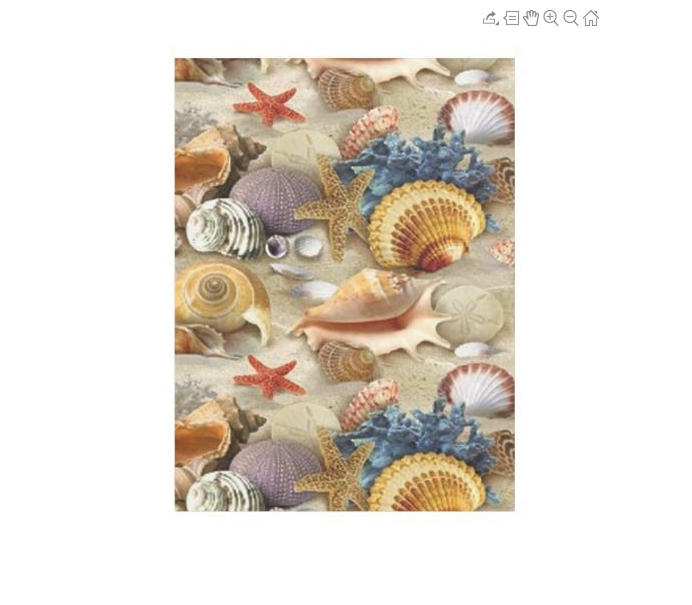

clear
% overlaid, 5, 17, shellfish, seashell, noise7 
filepath ="images\shellfish_four.jpg";
im = imread(filepath);

for i = 1:5
    roi = imcrop(im); % Calculate stats using given functions. Var names = tbl header names.
    txStats = statxture(roi);
    AvgGrayLvl = txStats(1);
    AvgContrst = txStats(2);
    Smoothness = txStats(3);
    ThrdMoment = txStats(4);
    Uniformity = txStats(5);
    Entropy = txStats(6);
    
    statsTable = table(filepath, AvgGrayLvl, AvgContrst, Smoothness, ThrdMoment, Uniformity, Entropy);
    % 
    % writetable(statsTable,'CropTextureStats.csv','Delimiter',',')  
    % type 'CropTextureStats.csv'% 
    t = readtable("CorrectRegionTextureStats.csv");
    t = [t; statsTable]; % Append.
    writetable(t,'CorrectRegionTextureStats.csv','Delimiter',',') 
%     type 'ErroneousRegionTextureStats.csv'
end

function t = statxture(f, scale)
%STATXTURE Computes statistical measures of texture in an image.
%   T = STATXURE(F, SCALE) computes six measures of texture from an
%   image (region) F. Parameter SCALE is a 6-dim row vector whose
%   elements multiply the 6 corresponding elements of T for scaling
%   purposes. If SCALE is not provided it defaults to all 1s.  The
%   output T is 6-by-1 vector with the following elements:
%     T(1) = Average gray level
%     T(2) = Average contrast
%     T(3) = Measure of smoothness
%     T(4) = Third moment
%     T(5) = Measure of uniformity
%     T(6) = Entropy
%
%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.5 $  $Date: 2004/11/04 22:33:43 $

if nargin == 1
    scale(1:6) = 1;
else % Make sure it's a row vector.
    scale = scale(:)';
end

% Obtain histogram and normalize it.
p = imhist(f);
p = p./numel(f);
L = length(p);

% Compute the three moments. We need the unnormalized ones
% from function statmoments. These are in vector mu.
[~, mu] = statmoments(p, 3); % Hole for the first variable.

% Compute the six texture measures:
% Average gray level.
t(1) = mu(1);
% Standard deviation.
t(2) = mu(2).^0.5;
% Smoothness.
% First normalize the variance to [0 1] by
% dividing it by (L-1)^2.
varn = mu(2)/(L - 1)^2;
t(3) = 1 - 1/(1 + varn);
% Third moment (normalized by (L - 1)^2 also).
t(4) = mu(3)/(L - 1)^2;
% Uniformity.
t(5) = sum(p.^2);
% Entropy.
t(6) = -sum(p.*(log2(p + eps)));

% Scale the values.
t = t.*scale;
end

function [v, unv] = statmoments(p,  n)
    %STATMOMENTS Computes statistical central moments of image histogram.
    %   [W, UNV] = STATMOMENTS(P, N) computes up to the Nth statistical
    %   central moment of a histogram whose components are in vector
    %   P. The length of P must equal 256 or 65536.
    %
    %   The program outputs a vector V with V(1) = mean, V(2) = variance,
    %   V(3) = 3rd moment, . . . V(N) = Nth central moment. The random
    %   variable values are normalized to the range [0, 1], so all
    %   moments also are in this range.
    %
    %   The program also outputs a vector UNV containing the same moments
    %   as V, but using un-normalized random variable values (e.g., 0 to
    %   255 if length(P) = 2^8). For example, if length(P) = 256 and V(1)
    %   = 0.5, then UNV(1) would have the value UNV(1) = 127.5 (half of
    %   the [0 255] range).
    %     
    %   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
    %   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
    %   $Revision: 1.3 $  $Date: 2003/05/24 22:43:02 $
    
    Lp = length(p);
    if (Lp ~= 256) && (Lp ~= 65536)
        error('P must be a 256- or 65536-element vector.');
    end
    G = Lp - 1;
    
    % Make sure the histogram has unit area, and convert it to a
    % column vector.
    p = p/sum(p); p = p(:);
    
    % Form a vector of all the possible values of the
    % random variable.
    z = 0:G;
    
    % Now normalize the z's to the range [0, 1].
    z = z./G;
    
    % The mean.
    m = z*p;
    
    % Center random variables about the mean.
    z = z - m;
    
    % Compute the central moments.
    v = zeros(1, n);
    v(1) = m;
    for j = 2:n
        v(j) = (z.^j)*p;
    end
    
    if nargout > 1
        % Compute the uncentralized moments.
        unv = zeros(1, n);
        unv(1)=m.*G;
        for j = 2:n
            unv(j) = ((z*G).^j)*p;
        end
    end
end